# **Bayesian Optimisation Example**

**SECTION 1.0**

Goal: *maximise the function f(x) = x.*sin( x );  in the interval [0, 10]*

clear
close all
x = linspace( 0, 10, 501 ).';
f = x.*sin( x );


Extract 7 points for training an initial surrogate model & plot the results:

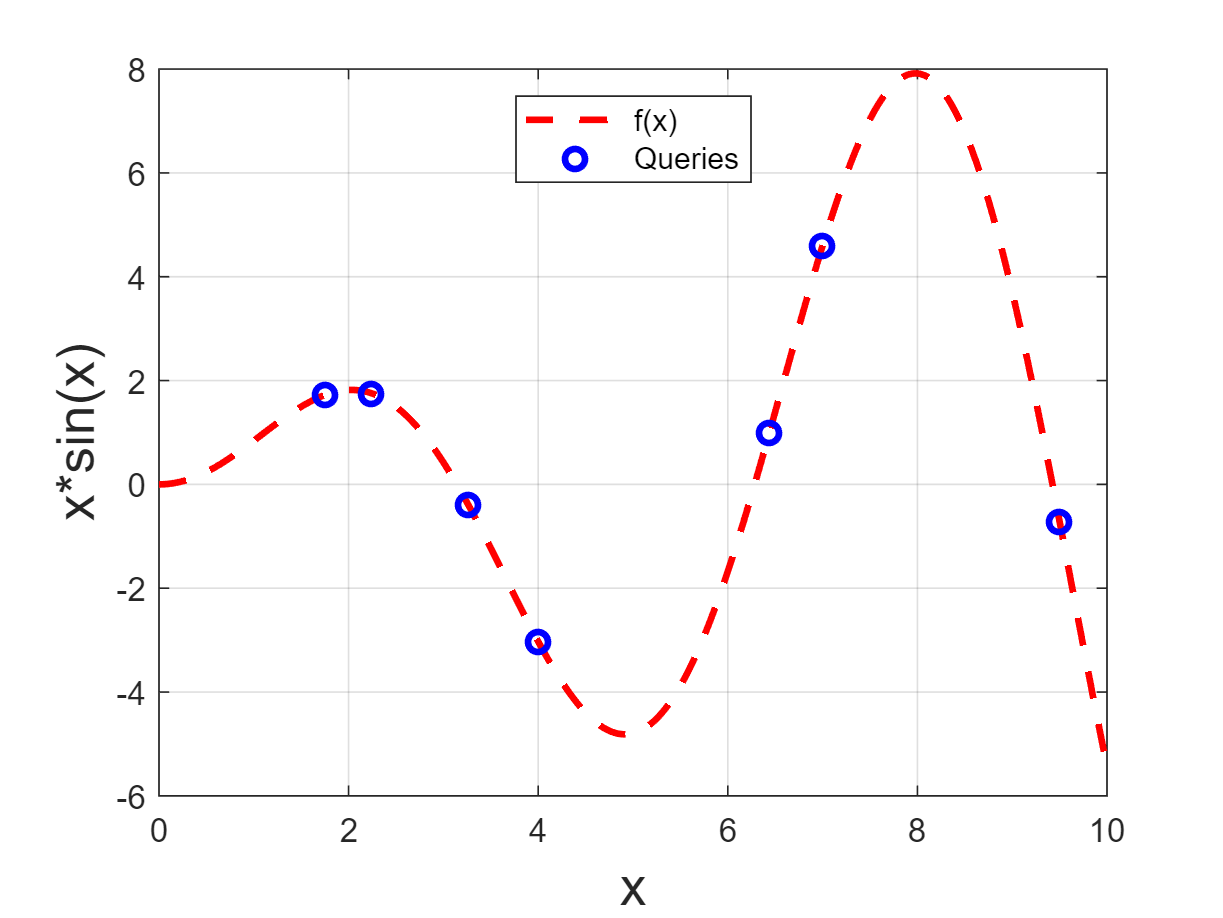

X = [ 9.5, 2.24, 4, 1.76, 3.26, 6.44, 7.0 ].';
Y = X .* sin( X );
plot( x, f, 'r--', X, Y, 'bo', 'LineWidth', 2 );
grid on
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
legend( "f(x)", "Queries", "Location", "north")

**SECTION 2.0**

Create the Bayesian Optimisation object. Assume a Gaussian Process Regression model and the Upper Confidence Bound acquisition function

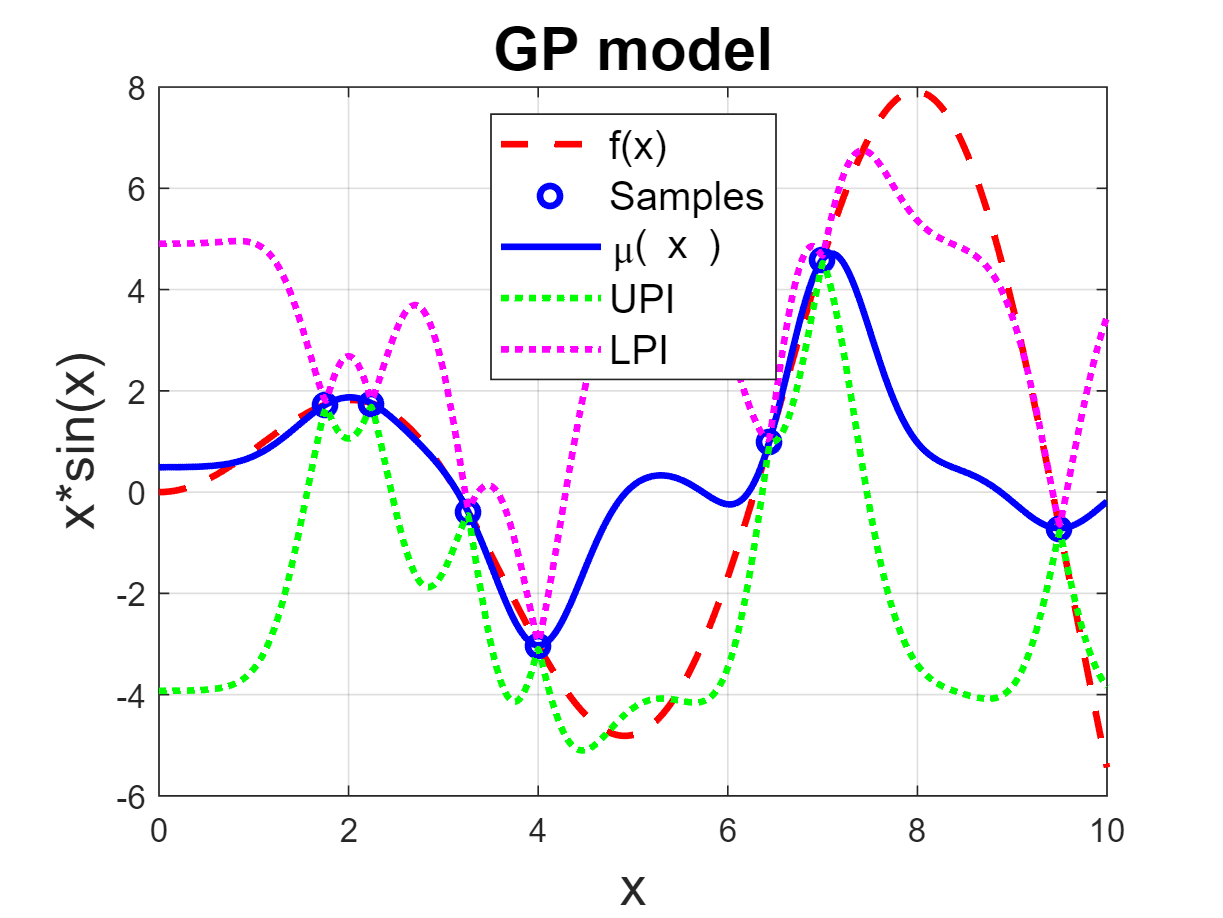

B = bayesOpt( "gpr", "ucb");
B = B.conDataCoding( 0, 10 );
B = B.setTrainingData( X, Y );
[ Yp, ~, Yint] = B.predict( x, 0.05 );
close all
figure;
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', 'LineWidth', 2);
grid on
legend( "f(x)", "Samples", "\mu( x )", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );
hold on;
plot(  x, Yint( :,1 ), 'g:', x, Yint( :,2 ), 'm:', 'LineWidth', 2);
legend( "f(x)", "Samples", "\mu( x )", "UPI", "LPI", 'Location', 'north', "FontSize", 12 );

**SECTION 3.0**

Maximise the acquisition function

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -4.608318e+00    0.000e+00    2.418e+00
    1      10   -4.693280e+00    0.000e+00    2.433e+00    2.500e-01
    2      12   -4.830499e+00    0.000e+00    3.414e-01    1.254e-01
    3      14   -4.832916e+00    0.000e+00    2.740e-02    1.543e-02
    4      16   -4.832931e+00    0.000e+00    1.613e-04    1.146e-03
    5      18   -4.832931e+00    0.000e+00    1.252e-07    6.787e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

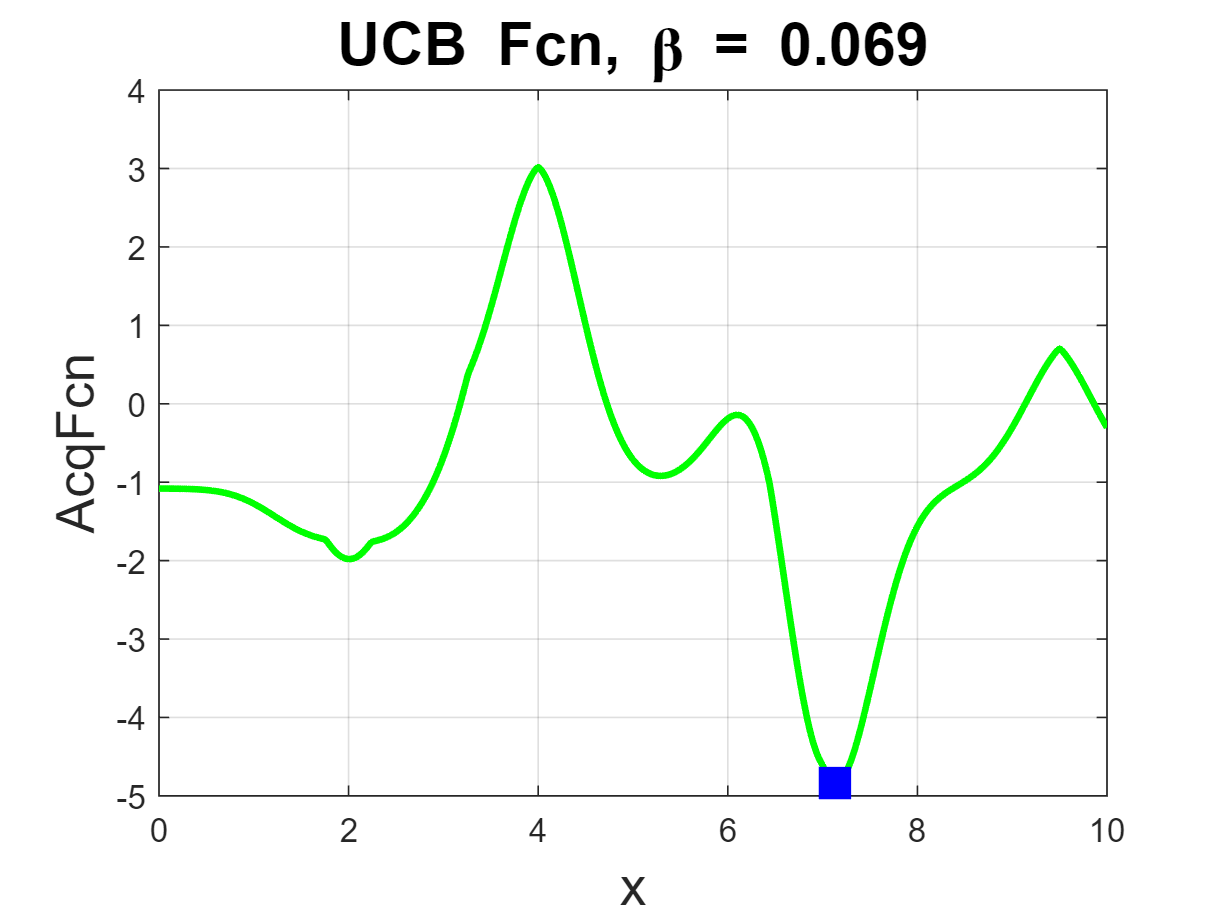

U = B.AcqObj;
figure;
A = U.evalFcn( x, U.Beta );
plot( x, A, 'g-', 'LineWidth', 2); grid on
xlabel( "x", "FontSize", 16 )
ylabel( "AcqFcn", "FontSize", 16 )
switch B.AcqFcn
    case "ucb"
        Tstr = sprintf( "UCB Fcn, \\beta = %4.3f", U.Beta );
    case "ei"
        Tstr = sprintf( "EI Fcn, \\beta = %4.3f", U.Beta );
    otherwise
        Tstr = sprintf( "AEI Fcn, [\\beta_0, M_e, \\Delta] = [ %3.2f, %3.2f, %4.3f]",...
            B.HyperPar);
end
title( Tstr, "FontSize", 18 ); 
hold on, plot( B.Xnext, B.AcqObj.evalFcn( B.Xnext ), "bs", "MarkerSize", 12, "MarkerFaceColor", "blue" );
grid on
hold off

**SECTION 4.0**

Query f(x) at the suggested value and update the GP model

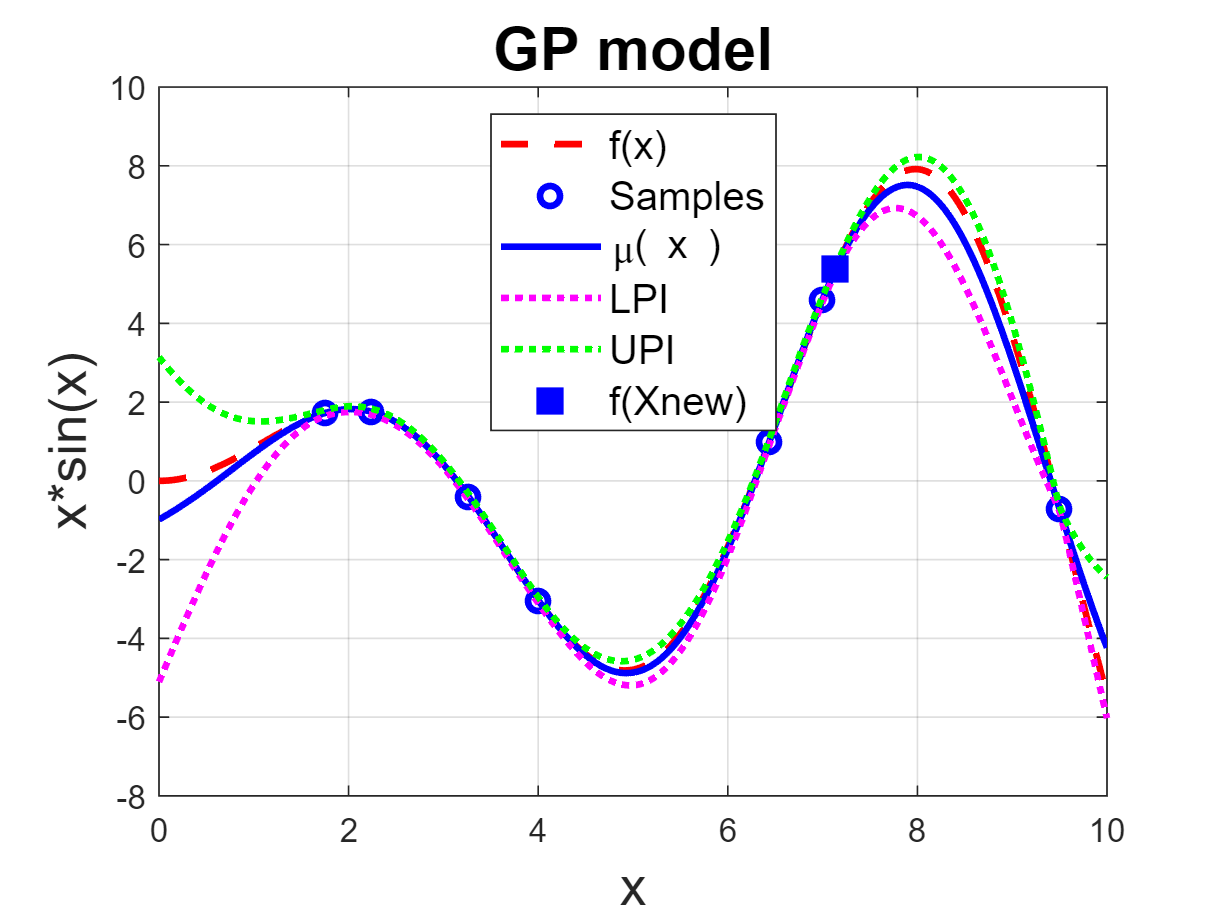

figure;
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
[ Yp, ~, Yint ] = B.predict( x );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );

**SECTION 5.0**

Iteration 2. Now re-optimise the acquisition function and add the new query to the training data and retrain the surrogate model.

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -7.920395e+00    0.000e+00    6.049e-03
    1       7   -7.920397e+00    0.000e+00    3.072e-05    7.561e-04
    2       9   -7.920397e+00    0.000e+00    6.945e-07    3.821e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<

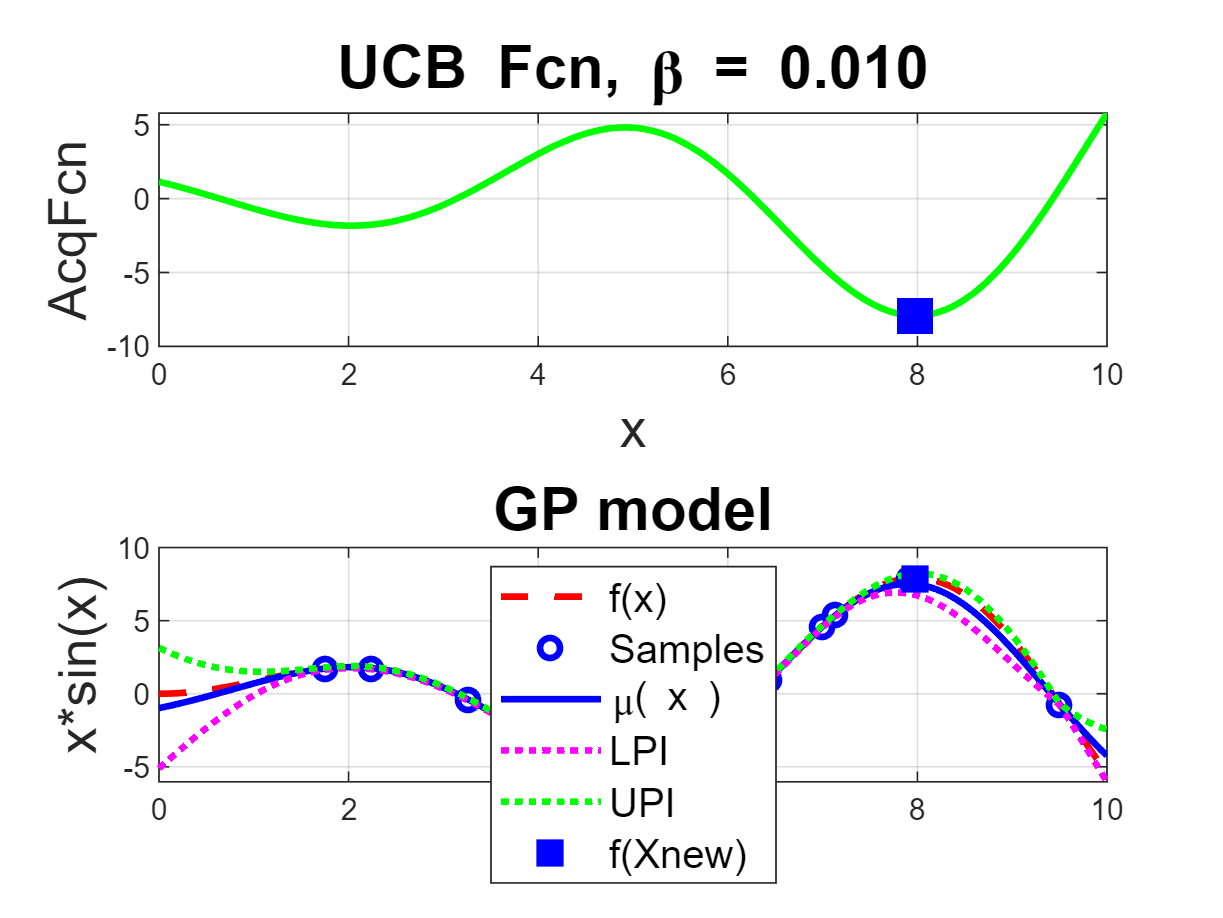

figure;
Xnew = B.Xnext;
subplot(2,1,1), plot( x, B.AcqObj.evalFcn( x ), 'g-', Xnew, B.AcqObj.evalFcn( Xnew ), 'bs', 'MarkerSize', 12,'LineWidth', 2, 'MarkerFaceColor','blue');
grid on
xlabel( "x", "FontSize", 16 )
ylabel( "AcqFcn", "FontSize", 16 )
switch B.AcqFcn
    case "ucb"
        Tstr = sprintf( "UCB Fcn, \\beta = %4.3f", U.Beta );
    case "ei"
        Tstr = sprintf( "EI Fcn, \\beta = %4.3f", U.Beta );
    otherwise
        Tstr = sprintf( "AEI Fcn, [\\beta_0, M_e, \\Delta] = [ %3.2f, %3.2f, %4.3f]",...
            B.HyperPar);
end
title( Tstr, "FontSize", 18 ); 
subplot(2,1,2)
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );